clc
clear
close all

Parsing data

load meass/ident01.mat

t = data(:,1);
T_vz = t(2)-t(1);
posX_cart = data(:,3);
phiX_effector = data(:,4);
input_voltage_x = data(:,5);

x = posX_cart-posX_cart(1);
u = input_voltage_x;
phi = phiX_effector-phiX_effector(1);

identification of cart

theta = fminsearch(@(theta)J_cart(theta,u,x,t),[1;0.2]);

K_v = theta(1);
T_v = theta(2);

F_cart = tf(K_v,[T_v 1 0])

F_cart =
 
       0.2176
  -----------------
  2.814e-05 s^2 + s
 
Continuous-time transfer function.
Model Properties



x_hat = lsim(F_cart,u,t);

vykreslenie

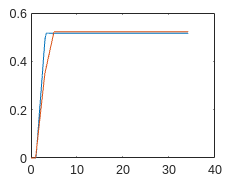

plot(t,x);
hold on
plot(t,x_hat);

identification of pendulum

theta = fminsearch(@(theta)J_pendulum(theta,x,phi,t),[-0.1;4;0.05]);

K_k = theta(1);
omega_0 = theta(2);
b = theta(3);

F_pendulum = tf([K_k*omega_0^2 0 0],[1 2*b*omega_0,omega_0^2])

F_pendulum =
 
        -1.371 s^2
  -----------------------
  s^2 + 0.01254 s + 12.96
 
Continuous-time transfer function.
Model Properties



phi_hat = lsim(F_pendulum,x,t);

vykreslenie

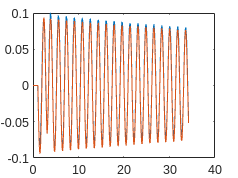

figure
plot(t,phi);
hold on
plot(t,phi_hat);

F_cart_num = [0	0	0.217598139970441];
F_cart_den = [2.813749053553513e-05	1	0];

F_pend_num = [-1.37069413493978	0	0];
F_pend_den = [1	0.0125366535496897	12.9568004970019];

% xlabel("Cas [s]")
% ylabel("poloha[m]")
% title("Identifikacia vozika")
% legend("namerana vzdialenost","identifikovany model")